# Leslie matrix

In this example we will consider a seven-stage model for the life cycle of an animal according to the following table:

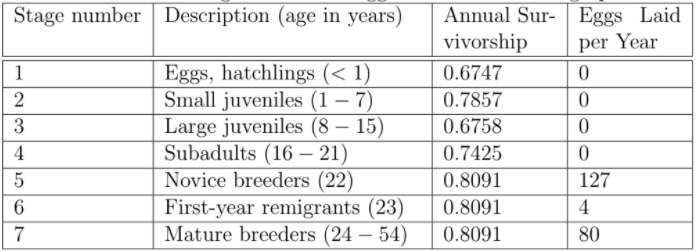

This will result in the following Leslie matrix:


$$L = \pmatrix{0&0&0&0&127&4&80 \cr
0.6747&0.7370&0&0&0&0&0 \cr
0&0.0486&0.6610&0&0&0&0\cr
0&0&0.0147&0.6907&0&0&0\cr
0&0&0&0.0518&0&0&0\cr
0&0&0&0&0.8091&0&0\cr
0&0&0&0&0&0.8091&0.8089

}$$


With initial condition:


$$X_0 = [200000, 130000,100000,70000,500,400,1100]^T$$


A = [0     0      0      0      127    4      80; 
    0.6747 0.7370 0      0      0      0      0 ; 
    0      0.0486 0.6610 0      0      0      0 ; 
    0      0      0.0147 0.6907 0      0      0 ; 
    0      0      0      0.0518 0      0      0 ;
    0      0      0      0      0.8091 0      0 ;
    0      0      0      0      0      0.8091 0.8089];
x0 = [200000 130000 100000 70000 500 400 1100].';

Note that we will first consider the unforced system.

## Defining data

We will start by generating new data. This can be done as follows $x(t+1) = A x(t) + Bu(t)$. Since we are considering the unforced system we get $x(t+1) = Ax(t)$.

datapoints = 20;
X = zeros(size(x0,1), datapoints);
X(:,1) = x0;
for idx = 2:datapoints
    X(:,idx) = A * X(:,idx - 1);
end

## System identification

### Complete data

To check if the data is informative for system identification we can use the `[bool, A, B] = isIdentifiable(X, U)` function. 

[bool, A_s] = isIdentifiable(X);
disp("Is the data informative for system identification?");

Is the data informative for system identification?


disp(bool);

   1



As we can see the data is informative for system identification. Now we can verify that the returned system is indeed the same as the provided system.

disp("Largest difference between actual A and calculated A_s");

Largest difference between actual A and calculated A_s


larges_difference = max(max(abs(A-A_s)))

larges_difference = 3.0733e-13

As we can see the matrices are equal up to working precision.

### What is the impact of sampling moment?

We will now consider a connected part of the array and see if it will have a effect on the returned A matrix. To be more specific, we will skip the first `n` data points from our current state data.

m = 12;
elements_skipped = 1:m;
max_difference = zeros(1,m);
for n = elements_skipped
    X_moment = X(:, n:end);
    [bool, A_moment] = isIdentifiable(X_moment);
    if bool 
        max_difference(n) = max(max(abs(A - A_moment)));
    else
        max_difference(n) = inf;
    end
end

As we can see it does have an impact on the informativity of the data. ***Need reasoning why this is happening.***

However informativity is not enough, since the solution should be unique independant of where on the trajectory we sample out data. To verify this we will look if there is a difference between the `A_s` matrix and the `A_moment` matrix.

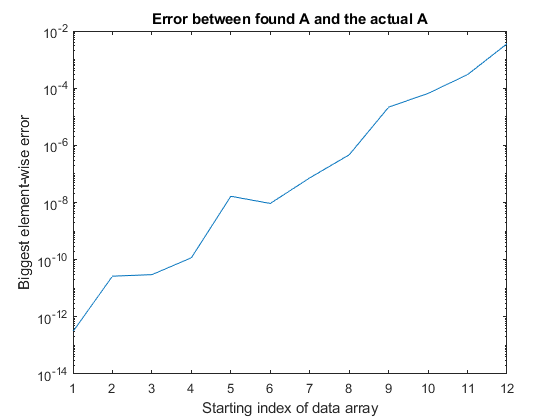

plot(elements_skipped, max_difference)
set(gca, 'YScale', 'log')
title(gca,"Error between found A and the actual A")
xlabel('Starting index of data array')
ylabel('Biggest element-wise error')
xlim([1 m])

As we can see the calulated `A` will get less and less *accurate due to rounding errors and machine presision*`.`

### What is the impact of sampling rate?

For this part of the example we will consider what happence if we sample our data on a fixed time, e.g. every 2 iterations. We whould assume this will result in the matrix `A^2`.

[bool, A_rate] = isIdentifiable(X(:,1:2:end));
disp("Is the data informative for system identification?");

Is the data informative for system identification?


disp(bool);

   1




disp("Largest difference between A^2 and calculated A_rate");

Largest difference between A^2 and calculated A_rate


larges_difference = max(max(abs(A^2 - A_rate)))

larges_difference = 1.5859e-10

As we can see, this does indeed result in the `A^2` matrix. However, we do need the sampling rate to be consistent. ***verify (with text or example)*** 

## Stability

We can also check if the data is informative for stability. To do this we use the function `bool = isInformStable(X)`. Since we also have the true system we can also check the result by comparing it to `bool = isStableD(A)`, which returns if the descrete time system is stable.

disp("Is the true system stable?");

Is the true system stable?


disp(isStableD(A));

   1



disp("Is the data informative for stability?")

Is the data informative for stability?


disp(isInformStable(X));

   1

